## Data Load

load('/Users/abhimanyubhowmik/Documents/MATLAB/Underwater Acoustics/Received.mat');

% Constants
totalTime = 6.4;
reflection = 10;
dt = 2e-04;
c = 1500;
initPos = 25;

[numRec, siglLen] = size(RecSig);

## Signal Plottting

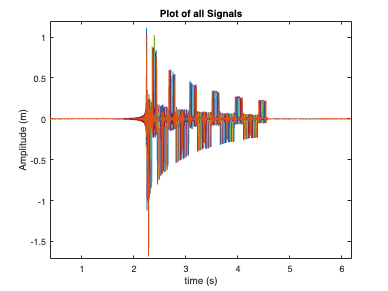

t = linspace(0, totalTime, siglLen);
% Recived Signal 1 and 5
r1 = RecSig(1,:);
r5 = RecSig(5,:);
r9 = RecSig(9,:);

figure(1)
plot(t,RecSig);
title('Plot of all Signals');
xlabel('time (s)'); 
ylabel('Amplitude (m)');
xlim([0.40 6.18])
ylim([-1.71 1.19])

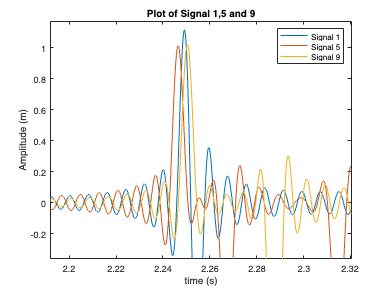


% Plotting around first peak
figure(2)
plot(t,r1)
hold on
plot(t,r5)
plot(t,r9)
title('Plot of Signal 1,5 and 9');
xlabel('time (s)'); 
ylabel('Amplitude (m)');
legend('Signal 1','Signal 5', 'Signal 9')
xlim([2.1920 2.3203])
ylim([-0.36 1.17])

## Calculating Time of Arrival of First Peak

peaks = [];
for i = 1:9
    firstPeak = max(RecSig(i,11000:11500));
    idx = find(RecSig(i,:)==firstPeak);
    peaks = [peaks, idx*dt];
    fprintf('Time taken to reach first peak %f for Reciever%d\n',idx*dt,i);

end

Time taken to reach first peak 2.249400 for Reciever1
Time taken to reach first peak 2.249200 for Reciever2
Time taken to reach first peak 2.247200 for Reciever3
Time taken to reach first peak 2.247200 for Reciever4
Time taken to reach first peak 2.246600 for Reciever5
Time taken to reach first peak 2.247400 for Reciever6
Time taken to reach first peak 2.247800 for Reciever7
Time taken to reach first peak 2.249200 for Reciever8
Time taken to reach first peak 2.250600 for Reciever9


## Signal 5

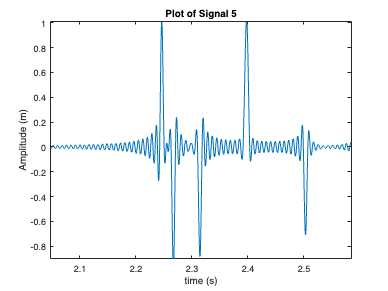

figure(3)
plot(t,r5)

title('Plot of Signal 5');
xlabel('time (s)'); 
ylabel('Amplitude (m)');

xlim([2.048 2.584])
ylim([-0.90 1.01])

## Backpropagation of time reverse recived signal

% Estimated Depth
H = 351.4;

% Exploration area (x,z axis)

X_Pos = linspace(940,1020,15);
Z_Pos = linspace(100,150,12.5);


plotArea = zeros(length(Z_Pos),length(X_Pos));
 
 for i = 1:length(X_Pos)
    for j = 1:length(Z_Pos)
        receivedSignal = zeros(size(RecSig));
        for k = 1:size(RecSig, 1)
            flipSig = flip(RecSig(k,:));
            out= Green(X_Pos(i),Z_Pos(j), 0, initPos*k, H, c, flipSig', dt, reflection);
            receivedSignal(k, :) = out;
        end
       
       receivedSignal = sum(receivedSignal, 1).^2;
       totalSignal = sum(receivedSignal, "all");
       
       totalSignal = 10*log10(totalSignal);
       plotArea(j,i) = totalSignal;

    end
 end


## Plotting Source

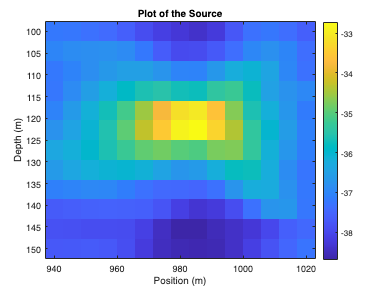

figure(4);
image(X_Pos,Z_Pos, plotArea, 'CDataMapping','scaled');
colorbar;
title('Plot of the Source');
xlabel('Position (m)') 
ylabel('Depth (m)')

## Green's Function

function [g]= Green(xr,zr,xs,zs,h,c,sig,dt,n_ref)

r_even_j= @(x,z,j) sqrt( (x-xs).^2 + (z-zs+(j)*h).^2 );
r_odd_j= @(x,z,j)sqrt ( (x-xs).^2 + (z+zs-(j+1)*h).^2 );

fs= 1/dt;
g=0;

    for j= -n_ref:n_ref
        if mod(j,2)==1
            eps= -1;
            rj= r_odd_j(xr,zr,j);
        else
            eps= 1;
            rj= r_even_j(xr,zr,j);
        end
        
        delta= delayseq(sig,rj/c,fs);
        gj= eps/(4*pi*rj)*delta;
        
        g=g-gj;
    end

end
